Assignment 5: In this assignment, another data set will be used, with 70 measurements taken when target is absent and 60 when target is present. This assignment is just to do chi-square test for the data set on different distributions (Rician, Nakagami, Gamma and Weibull). Then the Mean squared Error is calculated. The decision on rejecting or not, and the various chi-square testing resulting parameters will be covered in assignment 6.


data = table2array(ProjFall7);
data = data(~isnan(data));
data_sorted_des = sort(data, 'descend');
target_abs = data((1:70),:);
target_pre = data((71:130),:);

mean_abs = mean(target_abs);
mean_pre = mean(target_pre);
var_abs = var(target_abs);
var_pre = var(target_pre);



%This part for absent (H0)

%Weibull
parW_abs = fitdist(target_abs, 'Weibull');
a_abs = parW_abs.a

a_abs = 1.5819

b_abs = parW_abs.b

b_abs = 1.1230


%Rician
parR_abs=fitdist(target_abs, 'Rician');
sigma_abs = parR_abs.sigma

sigma_abs = 1.3738

s_abs = parR_abs.s

s_abs = 0.0795



%Nakagami
parN_abs = fitdist(target_abs,'nakagami');
mu_abs=parN_abs.mu

mu_abs = 0.4302

omega_abs=parN_abs.omega

omega_abs = 3.7802


%Gamma
parG_abs = fitdist(target_abs, 'gamma');
gammaa_abs = parG_abs.a

gammaa_abs = 1.1163

gammab_abs = parG_abs.b

gammab_abs = 1.3629

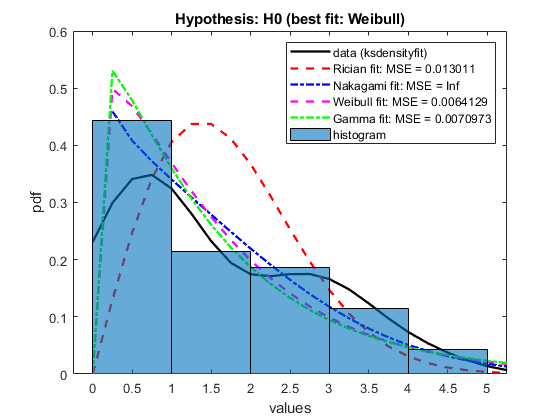


xx_abs=0:0.25:1.2*max(target_abs);
xx_pre=0:0.25:1.2*max(target_pre);

f_rician_abs = pdf('rician', xx_abs, s_abs, sigma_abs);
f_nakagami_abs = pdf('nakagami', xx_abs, mu_abs, omega_abs);
f_weibull_abs = pdf('weibull', xx_abs, a_abs, b_abs );
f_gamma_abs = pdf('gamma', xx_abs, gammaa_abs, gammab_abs);
[f_abs] = ksdensity(target_abs, xx_abs);

figure(1)
plot(xx_abs, f_abs, 'k-', xx_abs, f_rician_abs, ...
    'r--', xx_abs, f_nakagami_abs, 'b-.', ...
    xx_abs, f_weibull_abs, 'm--', xx_abs, ...
    f_gamma_abs, 'g-.', 'LineWidth', 1.7)
num_sample = length(xx_abs);

MSERic_abs = sum((f_abs - f_rician_abs).^2)/num_sample;
MSENaka_abs = sum((f_abs-f_nakagami_abs).^2)/num_sample;
MSEWeib_abs = sum((f_abs - f_weibull_abs).^2)/num_sample;
MSEGam_abs = sum((f_abs- f_gamma_abs).^2)/num_sample;
xlabel('values'), ylabel('pdf')
 
hold on

histogram(target_abs, 'Normalization', 'pdf')
title("Hypothesis: H0 (best fit: Weibull)")
legend('data (ksdensityfit)', ['Rician fit: MSE = ',...
    num2str(MSERic_abs)], ['Nakagami fit: MSE = ', ...
    num2str(MSENaka_abs)], ['Weibull fit: MSE = ', ...
    num2str(MSEWeib_abs)], ['Gamma fit: MSE = ', ...
    num2str(MSEGam_abs)], 'histogram')
hold off

%This part for present targets

%Weibull
parW_pre = fitdist(target_pre, 'Weibull');
a_pre = parW_pre.a

a_pre = 3.4291

b_pre = parW_pre.b

b_pre = 3.2056


%Rician
parR_pre=fitdist(target_pre, 'Rician');
sigma_pre = parR_pre.sigma

sigma_pre = 1.1261

s_pre = parR_pre.s

s_pre = 2.8328



%Nakagami
parN_pre = fitdist(target_pre,'nakagami');
mu_pre=parN_pre.mu

mu_pre = 2.0519

omega_pre=parN_pre.omega

omega_pre = 10.5611


%Gamma
parG_pre = fitdist(target_pre, 'gamma');
gammaa_pre = parG_pre.a

gammaa_pre = 6.8761

gammab_pre = parG_pre.b

gammab_pre = 0.4464

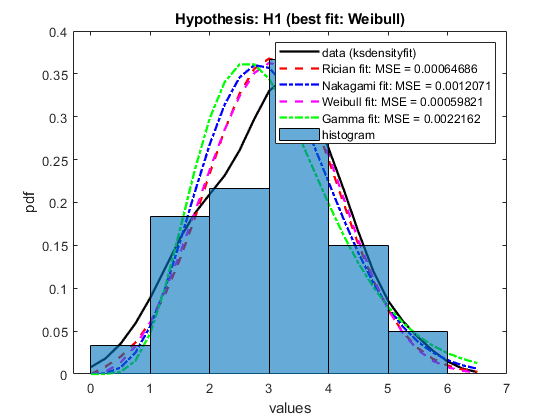


f_rician_pre = pdf('rician', xx_pre, s_pre, sigma_pre);
f_nakagami_pre = pdf('nakagami', xx_pre, mu_pre, omega_pre);
f_weibull_pre = pdf('weibull', xx_pre, a_pre, b_pre );
f_gamma_pre = pdf('gamma', xx_pre, gammaa_pre, gammab_pre);
[f_pre] = ksdensity(target_pre, xx_pre);

figure(2)
plot(xx_pre, f_pre, 'k-', xx_pre, f_rician_pre, ...
    'r--', xx_pre, f_nakagami_pre, 'b-.', ...
    xx_pre, f_weibull_pre, 'm--', xx_pre, ...
    f_gamma_pre, 'g-.', 'LineWidth', 1.7)
num_sample2 = length(xx_pre);

MSERic_pre = sum((f_pre - f_rician_pre).^2)/num_sample2;
MSENaka_pre = sum((f_pre-f_nakagami_pre).^2)/num_sample2;
MSEWeib_pre = sum((f_pre - f_weibull_pre).^2)/num_sample2;
MSEGam_pre = sum((f_pre- f_gamma_pre).^2)/num_sample2;
xlabel('values'), ylabel('pdf')
 
hold on

histogram(target_pre, 'Normalization', 'pdf')
title("Hypothesis: H1 (best fit: Weibull)")
legend('data (ksdensityfit)', ['Rician fit: MSE = ',...
    num2str(MSERic_pre)], ['Nakagami fit: MSE = ', ...
    num2str(MSENaka_pre)], ['Weibull fit: MSE = ', ...
    num2str(MSEWeib_pre)], ['Gamma fit: MSE = ', ...
    num2str(MSEGam_pre)], 'histogram', 'Location', "northeast")